# Unicycle Model

The kinematic model of the unicycle can be defined as follows:

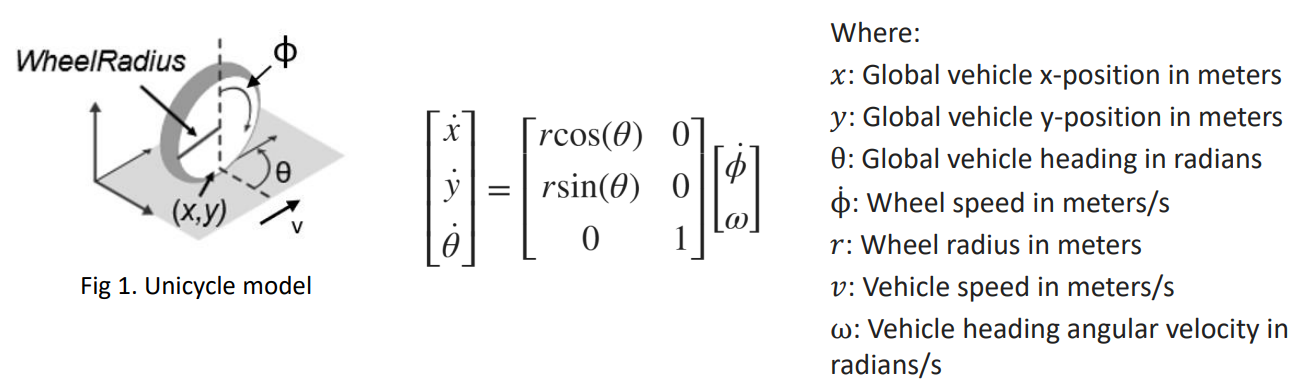

However, this is a model that employs the** wheel speed **$\dot \phi$ as a control input. It's possible to change the model to be controlled with the** vehicle’s speed** $v$ and heading angular velocity $\omega$ by changing $𝑣 = 𝑟\dot \phi$

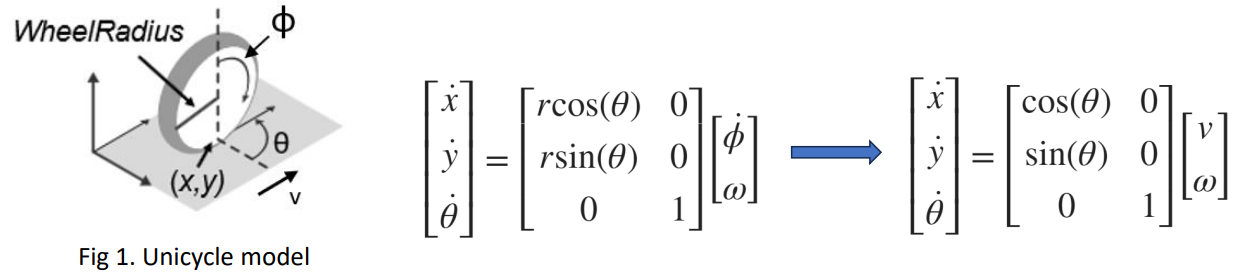

## **Part 1: Custom Unicycle Kinematic Model**

Here we use a function called `unicycle ``that` implements a simplified unicycle kinematic model. The model defines the vehicle’s state (position x, y, and orientation θ) and computes its derivatives as follows:

- **Wheel Radius (**`r`**)** is set to 0.1 m.

- **Wheel Speed (**$\dot \phi$**)** is set to 2 rad/s.

- **Linear Velocity (**`v`**)** is computed as $v = r \times \dot \phi$

- **Angular Velocity (**$\omega$**) **is fixed at $\frac{\pi}{4}$ rad/s.

The `ode45` function integrates these differential equations to produce the vehicle trajectory, which is then plotted.

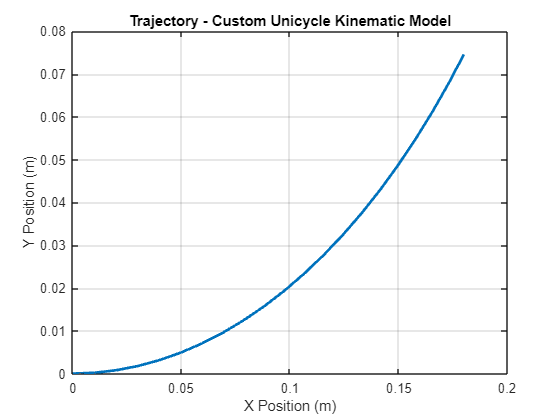

clc
clear
close all

% Custom Unicycle Kinematic Model
tspan = 0:0.05:1; 
initialState = [0 0 0];
[t, q] = ode45(@unicycle, tspan, initialState);

figure
plot(q(:,1), q(:,2), 'LineWidth', 2)
title('Trajectory - Custom Unicycle Kinematic Model')
xlabel('X Position (m)')
ylabel('Y Position (m)')
grid on

## **Part 2: MATLAB's Built-In Unicycle Kinematics**

Here we use the MATLAB's built-in `unicycleKinematics` function:

- An instance of `unicycleKinematics` is created with the modes `"VehicleInputs"` and `"VehicleSpeedHeadingRate"`.

- The model receives an input vector `[0.2, `$\frac{\pi}{4}$`]`, representing the vehicle speed and veichle heading angular velocity.

- A function handle is defined to compute the state derivative using the `derivative` method of the model.

- The system is integrated using `ode45`, and the resulting trajectory is plotted.

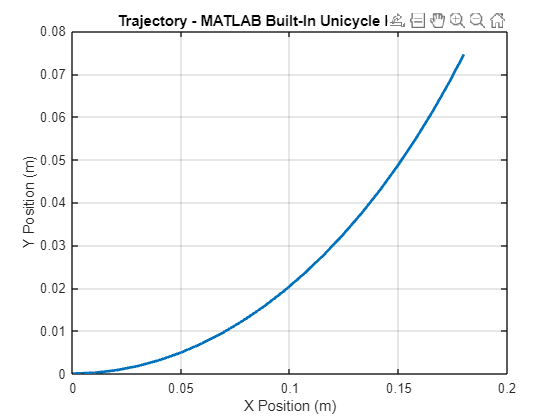

% Using MATLAB''s unicycleKinematics
input = [0.2, pi/4];
unicycleModel = unicycleKinematics("VehicleInputs", "VehicleSpeedHeadingRate");
[t, q_unicycle] = ode45(@(t, q_unicycle) derivative(unicycleModel, q_unicycle, input), tspan, initialState);

figure
plot(q_unicycle(:,1), q_unicycle(:,2), 'LineWidth', 2)
title('Trajectory - MATLAB Built-In Unicycle Kinematics')
xlabel('X Position (m)')
ylabel('Y Position (m)')
grid on

% Custom Unicycle Kinematic Model Function

function dq = unicycle(t, q)
    % Extract state variables
    x  = q(1);
    y  = q(2);
    th = q(3);

    % Model parameters
    r    = 0.1;  % Radius of the wheel (m)
    dphi  = 2;    % Wheel speed (rad/s)

    % Compute velocities
    v = r * dphi;   % Linear velocity (m/s)
    w = pi/4;      % Angular velocity (rad/s)

    % Compute state derivatives
    dq = [cos(th) 0; 
          sin(th) 0; 
          0       1] * [v; w];
end

Both methods allow us to compare the behavior of the custom unicycle model with MATLAB’s built-in functionality.